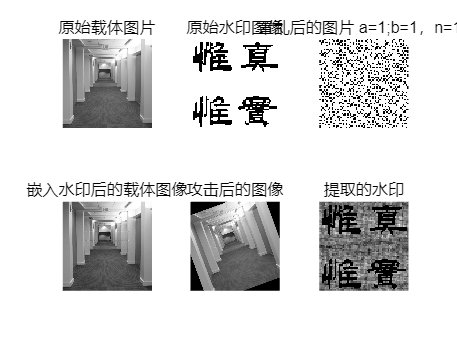

% close all
% clc
% clear 

M = 512; % 原图像长度
N = 64; % 水印图像长度

alpha=0.05;% 嵌入强度系数

% 打开原图、水印图
I = imread('hallway.jpg');
IG = imread('水印(二值).bmp');
G = IG;
subplot(2,3,1);
imshow(I);
title('原始载体图片');
subplot(2,3,2);
imshow(G,[]);
title('原始水印图像');

img=G;%读取图片，根据Arnold变换的条件，图像必须是正方形
mysize=size(img);%当只有一个输出参数时，返回一个行向量，该行向量的第一个元素时矩阵的行数，第二个元素是矩阵的列数。

%置乱与逆置乱必须采用共同参数的时候,就相当于密码，才能解密，让图像复原
n=10;%迭代次数
a=1;b=1;

%置乱操作
h = N;
w = N;
imgnnn=zeros(h,w);
for i=1:n
    for y=1:h
        for x=1:w           
            xx=mod((x-1)+b*(y-1),N)+1;   %mod取余操作，(a,b)就是a除以b的余数
            yy=mod(a*(x-1)+(a*b+1)*(y-1),N)+1;        
            imgnnn(yy,xx)=img(y,x);                
        end
    end
    img=imgnnn;
end
imgnnn = uint8(imgnnn);
 
subplot(2,3,3);
imshow(imgnnn,[])%置乱后的图片
title('置乱后的图片 a=1;b=1，n=10');
% imwrite (imgnnn,'置乱后的图片.bmp');  %生成图像保存功能

G=imgnnn;
G = double(G) * 255; % 将逻辑值 1 转换为 255

%Step 1
%对G进行SVD分解
[U,S,V] = svd(G);% 对G进行SVD分解，得到U、S、V矩阵

%Step 2
%进行2级离散小波变换
[LL1, LH1, HL1, HH1] = dwt2(I, 'haar');
[LL2, LH2, HL2, HH2] = dwt2(LL1, 'haar');%128*128

%Step 3
%选出最优嵌入块 
img=HH2;
% 初始化变量
img_size = [128 128];
sub_size = 64;
max_entropy = -Inf;
max_entropy_pos = [0, 0];
max_entropy_sub = [];

% % 遍历图像中的所有64×64子片段
% for i = 1:img_size(1) - sub_size + 1
%     for j = 1:img_size(2) - sub_size + 1
%         % 提取子片段
%         sub_img = img(i:i+sub_size-1, j:j+sub_size-1);
% 
%         % 计算子片段的信息熵
%         current_entropy = entropy(sub_img);
% 
%         % 更新最大信息熵及其位置
%         if current_entropy > max_entropy
%             max_entropy = current_entropy;
%             max_entropy_pos = [i, j];
%             max_entropy_sub = sub_img;
%         end
%     end
% end

% i = max_entropy_pos(1);
% j = max_entropy_pos(2);

i=32;
j=32;

H_I = HH2(i:i+sub_size-1, j:j+sub_size-1);
B = dct2(H_I);

%Step 5
%对B进行奇异值分解,嵌入水印
[U1,S1,V1] = svd(B);
S2 = S1 + alpha * S;
B1 = U1 * S2 * V1;
H_I = idct2(B1);
HH2(i:i+sub_size-1, j:j+sub_size-1) = H_I;
LL1 = idwt2(LL2,LH2,HL2,HH2,'haar');
W = idwt2(LL1,LH1,HL1,HH1,'haar');
W = uint8(W);
aW = W;

%% 攻击
%高斯滤波攻击
% H = fspecial('gaussian',3,0.4);
% aW = imfilter(W,H);

%高斯噪声
% mean = 0; % 均值为0
% variance = 0.003; % 方差为0.01
% 
% aW = imnoise(aW, 'gaussian', mean, variance);


% 压缩攻击
% quality = 50;
% % aW = imresize(aW, 0.5); % 缩小图像
% imwrite(aW, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
% aW = imread('temp.jpg'); % 重新读取JPEG图像
% % aW = imresize(aW, 2); % 放大图像
% 
% 剪切攻击
% aW=W;
% r = 0.3; % 剪切比例为30%
% sz = size(W);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% % x1=300;
% % y1=300;
% aW(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
 
% 旋转攻击
angle = 20; % 旋转角度为20度
aW = imrotate(aW, angle, 'bilinear', 'crop');
% 
% aW = imrotate(aW, -angle, 'bilinear', 'crop');


% 
% tif=imread("cameraman.tif");
% aW = padarray(tif, [256, 256], 'post');  % 在图像右侧和下方填充128像

%
% aW = rand(512, 512);
% aW = imread('flamingos.jpg');

%提取水印
%aW=double(aW);
[LL3, LH3, HL3, HH3] = dwt2(aW, 'haar');
[LL4, LH4, HL4, HH4] = dwt2(LL3, 'haar');%128*128
H_I2 = HH4(i:i+sub_size-1, j:j+sub_size-1);
B2 = dct2(H_I2);
[Uw,Sw,Vw] = svd(B2);
Sx = (Sw - S1)/alpha;
B2 = U * Sx * V.';
A = B2;

%逆置乱复原
img2=A;%读取置乱图片
for i=1:n
    for y=1:h
        for x=1:w            
            xx=mod((a*b+1)*(x-1)-b*(y-1),N)+1;%matlab索引中不能是0，要从1开始
            yy=mod(-a*(x-1)+(y-1),N)+1  ;        
            imgnnn(yy,xx)=img2(y,x);                   
        end
    end
    img2=imgnnn;
end
imgnnn = uint8(imgnnn);

% imgnnn = imbinarize(imgnnn);  % 自动选择阈值;

subplot(2,3,4);
imshow(W,[]);
title('嵌入水印后的载体图像');
subplot(2,3,5);
imshow(aW,[]);
title('攻击后的图像');
subplot(2,3,6);
imshow(imgnnn,[]);
title('提取的水印');


% 计算PSNR值
W = uint8(W);
psnr_val = psnr(I, W);
fprintf('原图与嵌入水印后的图PSNR为： %f.\n', psnr_val);

原图与嵌入水印后的图PSNR为： 42.236217.



aW = uint8(aW);
psnr_val2 = psnr(I, aW);
fprintf('原图与嵌入水印后被攻击的图PSNR为： %f.\n', psnr_val2);

原图与嵌入水印后被攻击的图PSNR为： 11.970940.



% 计算NC值
% C = normxcorr2(IG*256, imgnnn);
% % 提取最大相关系数值
% nc_value = max(C(:));
% % 输出结果
% fprintf('归一化相关性（NC）值为：%.5f\n', nc_value);

% % 计算NC值
NC = corr2(IG*256, imgnnn);
disp(['归一化相关系数 NC = ', num2str(NC)]);

归一化相关系数 NC = 0.88278



% 计算SSIM值
[ssimval, ~] = ssim(I, W);
fprintf('SSIM值为: %.4f\n', ssimval);

SSIM值为: 0.9788



imwrite(aW, 'h5.jpg'); % 保存为JPEG格式

close all
sss=imgnnn;
subplot(1,2,1);
imshow(sss,[]);
title('矫正前提取的水印');

close all
ssss=imgnnn;
subplot(1,2,1);
imshow(sss,[]);
title('矫正前提取的水印');
subplot(1,2,2);
imshow(ssss,[]);
title('矫正后提取的水印');


close all
subplot(1,2,1);
imshow(I,[]);
title('原始载体图像');
subplot(1,2,2);
imshow(W,[]);
title('含水印图像');
% subplot(1,2,1);
% imshow(aW);
% title('高斯噪声攻击');
% subplot(1,2,2);
% imshow(imgnnn,[]);
% title('提取的水印图像');